clc
clear all

load("rt40_mat_files\DOA_rt40.mat")
load("rt40_mat_files\pressure_rt40.mat")

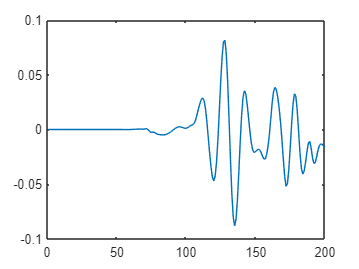

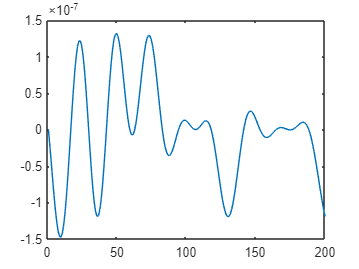

% Read stereo signal
S = audioread(['Measurements_Team4\594223__szegvari__battle-cinematic-soundtrack-music-atmo-background.wav']);
% Choose 10 seconds and resample
Sr = resample(S(1:44.e3*10,:),480,441);

%TODO: What RIRs/SIRs to use, demo works with ir_left and ir_right


lspSetupNames = {'2.1','5.1','22.2','AALTO_24'};
for lspSetups = 1:length(lspSetupNames)
        % load default 5.1 setup and define some parameters with custom values
    s = createSynthesisStruct('Binaural',true,...
        'DefaultArray',lspSetupNames{lspSetups},...
        'HRTFset',28,... % <---- CIPIC HRTF subject number
        'snfft',length(P{1}),...
        'fs',192e3,...
        'c',343);
    % You always need to define 'snfft'
    
        Hbin = cell(1,2);
    H = cell(1,2);
    for channel = 1:2
        [~, Hbin{channel}] = synthesizeSDMCoeffs(P{channel},DOA{channel}, s);
    end

    % Resample H to 48e3 [Hz] sampling frequency for auralization
    Hbin{1} = resample(Hbin{1},1,4);
    Hbin{2} = resample(Hbin{2},1,4);
    
    Y = zeros(size(Sr,1),2);
    for channel = 1:2 % measured left and right channel
        for lsp = 1:2 % left and right ear
            % Convolution with Matlab's overlap-add
            Y(:,lsp) = Y(:,lsp) +  fftfilt(Hbin{channel}(:,lsp),Sr(:,channel));
        end
    end
    % Y contains the auralization of the spatial IRs with S


Error using load
Unable to find file or directory 'CIPIC_hrtf_database\standard_hrir_database\subject_028\hrir_final.mat'.

Error in createSynthesisStruct (line 431)
    load([cipic_path 'subject_' cipic_name fp 'hrir_final.mat'])

    disp('Started Auralization');tic
    savename = [ir_filename '_' audio_filename '_Binaural_' lspSetupNames{lspSetups} '.wav'];
    if max(abs(Y(:))) > 1
        Y = Y/max(abs(Y(:)))*.9;
        disp('Sound normalized, since otherwise would have clipped')
    end
    disp(['Ended Auralization in ' num2str(toc) ' seconds.'])
    disp('Started writing the auralization wav file')
    disp([savename  ' on the disk.']);tic
    audiowrite(savename,Y/10,s.fs/4) % <---- save the result as wav
    info = audioinfo(savename);
    disp('Wrote ... ');
    disp(info)
    disp(['... in ' num2str(toc) ' seconds'])
end